# Passive Solar House

Lilo Heinrich & Julia Hunt

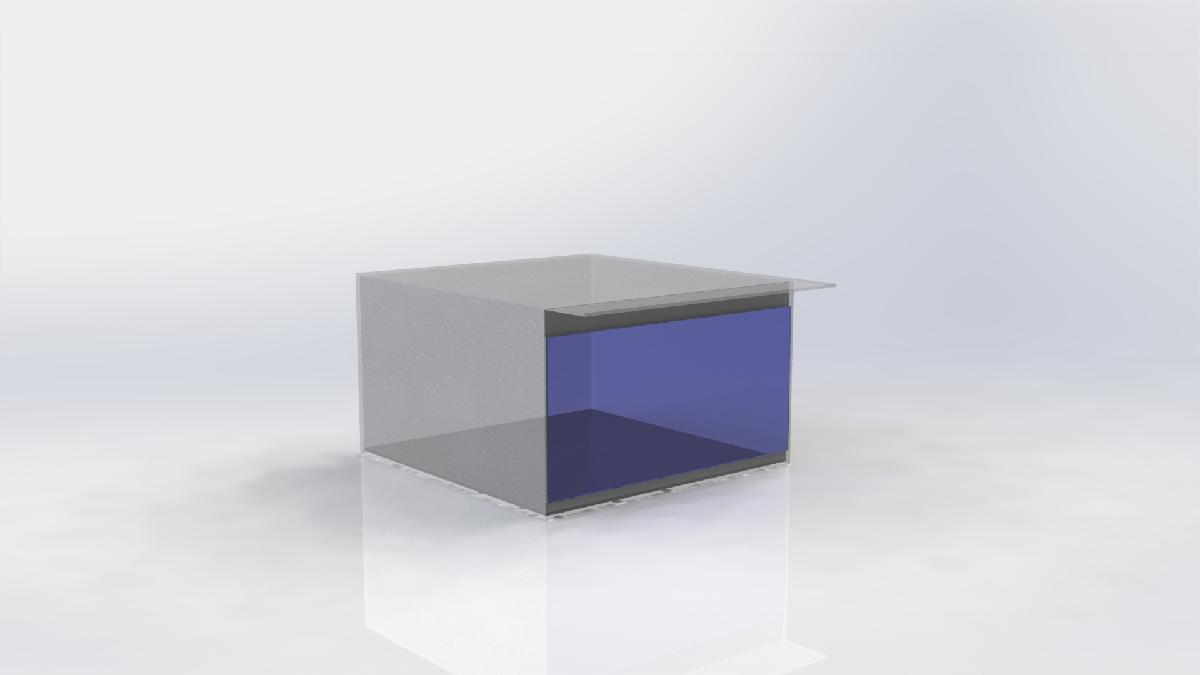

### **Part 1: **Sweeping the variables

**Defining Constants**

All of the constants below were taken from the project specification document defaults, except for t_span, the time span we are runnig the simulation over which we defined as 30 days.

clear all

T_out = -3; % Outside temperature (deg Celsius)
T_init = T_out; %Initial air temp inside house (deg Celsius)
h_in = 15; % convective + radiative heat transfer coefficient inside house (W/m^2-K)
h_out = 30; % convective + radiative heat transfer coefficient outside house (W/m^2-K)
h_window = 0.7;  % heat transfer coefficient through double-paned window (W/m^2-K)
k_wall = 0.05; % thermal conductivity of wall (W/m-K)

height_in = 3; % internal height of house (m)
length_in = 5.1; % internal length of house (m)
depth_in = 5; % internal depth of house (m)
A_floor = length_in*depth_in; % Surface area of thermal mass/floor (m^2)

rho_floor = 3000; % density of thermal storage tile floor (kg/m^3)
cp_floor = 800; % Specific heat of tile floor @ constant pressure (J/kg-K)

tspan = [0 3600*24*30]; % set range of values for t (in this case 30 days)
y0 = T_init; % set initial temperature inside hoophouse

Here we set up the range of values to sweep for the thickness of the wall and floor:

delta_wall_start = 0.005;
delta_wall_step = 0.005;
delta_wall_numsteps = 30;
delta_wall_series = zeros(1,delta_wall_numsteps);

for i=1:delta_wall_numsteps
    delta_wall_series(i) = delta_wall_start + delta_wall_step*(i-1);
end

delta_floor_start = 0.05;
delta_floor_step = 0.01;
delta_floor_numsteps = 40;
delta_floor_series = zeros(1,delta_floor_numsteps);

for i=1:delta_floor_numsteps
    delta_floor_series(i) = delta_floor_start + delta_floor_step*(i-1);
end

delta_floor_series

delta_floor_series =     0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400


delta_wall_series

delta_wall_series =     0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500


temp_sweep = zeros(length(delta_floor_series), length(delta_wall_series), 2); % 4);
size(temp_sweep)

ans =     40    30     2


Now we sweep through each combination of wall and floor thickness, calculate all of the dependent variables, then find the minimum and maximum temperature of the air in the house over 30 days:

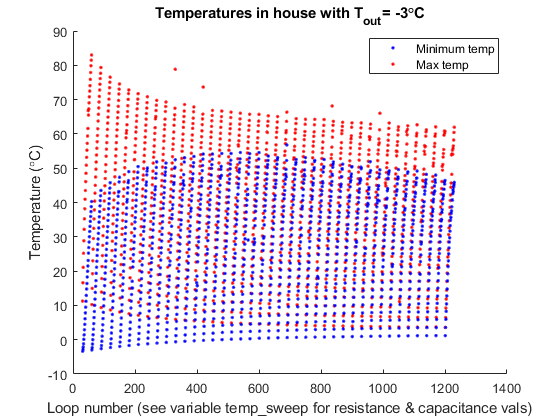

clf; hold on

for i=1:length(delta_floor_series)
    delta_floor = delta_floor_series(i); %Thickness of tile floor (m); this is our variable
    
    for k=1:length(delta_wall_series)
        delta_wall = delta_wall_series(k); % Wall thickness (m); this is our variable
        
        % % % Our logic on the area of the walls may be a bit funky. We should
        % check this logic later.
        A_wall = 2*(length_in+delta_wall)*(depth_in+delta_wall) + ... %floor & ceiling
                 2*(length_in+delta_wall)*(height_in+delta_wall) + ... %east & west walls
                 (height_in+delta_wall)*(depth_in+delta_wall) + ... %north wall
                 (0.4+0.2)*(depth_in+delta_wall); % south facing wall
        A_window = 2.6*depth_in; %Area of south-facing window (m^2)
        
        % % Calculate R1 & R2
        R1 = 1/(h_in*A_floor); % thermal resistance between thermal mass and air inside house (K/W)
        R2_wall = 1/(h_in*A_wall) + delta_wall/(k_wall*A_wall) + 1/(h_out*A_wall); %thermal resistance between inside & outside through wall
        R2_window = 1/(h_in*A_window) + 1/(h_window*A_window) + 1/(h_out*A_window); %thermal resistance between inside & outside through window
        R2 = ((R2_wall)^-1 + (R2_window)^-1)^-1; % total thermal resistance between inside air and outside air
        
        % % Calculate heat capacity of thermal mass as:  mc = rho*c*V = heat capacity (J/K)
        volume_floor = A_floor * delta_floor; % Volume of tile floor (m^3)
        C_floor = rho_floor * cp_floor * volume_floor; % heat capacity of tile floor (J/K)
        
        % % Define Q_in & q_solar
        % q_solar = -361*cos(pi*t/(12*3600)) + 224*cos(pi*t/(6*3600)) + 210; % solar flux (W/m^2)
        % Q_in = q_solar * A_window; % heat absorbed by heat storage unit (W)
        [t,T_floor] = ode45(@(t,T_floor) A_window*(-361*cos(pi*t/(12*3600)) + 224*cos(pi*t/(6*3600)) + 210)/C_floor ...
            - (T_floor - T_out)/((R1+R2)*C_floor), tspan, y0); % Solve the ODE
        
        T_air = T_floor - (T_floor-T_out)*R1/(R1+R2);
        air_max = max(T_air);
        air_min = min(T_air(round(length(T_air)/2):end));
        temp_sweep(i,k,:) = [air_max, air_min];
        
        plot(i*length(delta_wall_series) + k, air_min,'b.')
        plot(i*length(delta_wall_series) + k, air_max,'r.')
    end
end
    
xlabel('Loop number (see variable temp\_sweep for resistance & capacitance vals)')
ylabel('Temperature (\circC)')
title("Temperatures in house with T_{out}= "+T_out+"\circC")
legend('Minimum temp','Max temp','Location',"best")
hold off

The result of the sweep is the array temp_sweep, a 3D array of **delta_floor * delta_wall * temperature**, where:

- delta_floor is defined by the array delta_floor_series

- delta_wall is defined by the array delta_wall_series

- temperature is defined as the maximum and minimum of the calculated temperature of the house over 30 days, with the minumum taken in the second half of the month once the house has had time to warm up

In the table below, the maximum temperature is frame (:,:,1) and minimum is (:,:,2). The rows are wall thickness and the columns are floor thickness.

temp_sweep

temp_sweep = temp_sweep(:,:,1) =

   11.2627   16.6065   21.0981   25.2099   28.8427   32.1807   35.2445   38.1717   40.9436   43.5029   46.1101   48.5203   50.8898   53.1675   55.2512   57.2577   59.3804   61.5986   66.7960   65.4834   67.2898   69.0687   70.8085   72.4808   74.0744   75.9004   77.9068   79.8742   81.5021   83.0203
   10.2422   14.9669   19.2486   23.0139   26.3851   29.5181   32.4485   35.2195   37.8461   40.4079   42.7072   45.0093   47.4357   49.7198   51.7987   53.8403   55.8207   57.7269   59.5453   61.5068   63.7583   65.7210   67.5832   69.3019   70.9328   72.8052   74.4801   76.1358   77.6715   79.3491
    9.3866   13.9022   17.8278   21.3267   24.5227   27.5241   30.3382   33.0306   35.4492   37.9837   40.4429   42.6803   44.8930   47.0038   49.0129   51.0550   53.5023   55.5508   57.4710   59.4020   61.3044   63.1501   64.8966   66.6851   68.3873   70.1529   71.7994   73.4668   75.0685   76.5508
    8.6814   12.9417   16.6483   19.9117   23.0831   25.9815   

### Part 2: Finding solutions

Below are snapshots of how temperature responds with the thickness of the floor and the wall separately.

These trends show what we expected to see: the temperature fluctuates less the more insulation (thermal resistance) there is, and the average temperature increases when there is more ceramic tile flooring (heat storage capacity). Of course both of these graphs are each snapshots of only one of our two variables, so we can expect our temperature range to still need adjustment by the other variable.

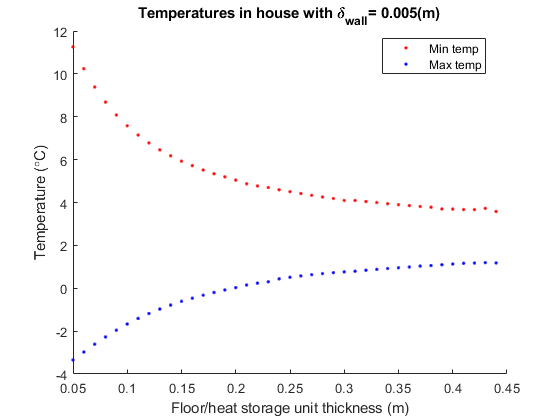

clf;
hold on
plot(delta_floor_series, temp_sweep(:,1,1), 'r.')
plot(delta_floor_series, temp_sweep(:,1,2), 'b.')
xlabel('Floor/heat storage unit thickness (m)')
ylabel('Temperature (\circC)')
title("Temperatures in house with \delta_{wall}= "+delta_wall_series(1)+"(m)")
legend('Min temp','Max temp','Location',"best")
hold off

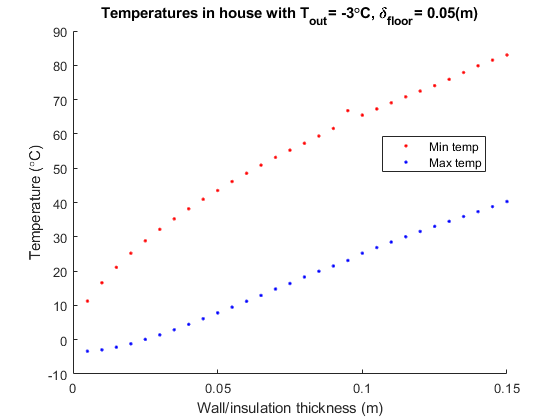


clf;
hold on
plot(delta_wall_series, temp_sweep(1,:,1), 'r.')
plot(delta_wall_series, temp_sweep(1,:,2), 'b.')
xlabel('Wall/insulation thickness (m)')
ylabel('Temperature (\circC)')
title("Temperatures in house with T_{out}= "+T_out+"\circC, \delta_{floor}= "+delta_floor_series(1)+"(m)")
legend('Min temp','Max temp','Location',"best")
hold off

Finding the comfortable values between the minimum and maximum desired temperature in degrees Celcius:

min_temp = 17; % the minimum desired temperature in degrees Celcius
max_temp = 25; % the maximum desired temperature in degrees Celcius
clear("golden_values")

x = 1;
for i = 1:size(temp_sweep,1)
    for k = 1:size(temp_sweep,2)
        if (temp_sweep(i,k,1) < max_temp) && (temp_sweep(i,k,2) > min_temp) 
            golden_values(x,:) = [delta_floor_series(i) delta_wall_series(k) temp_sweep(i,k,1) temp_sweep(i,k,2)];
            x = x+1;
        end
    end
end
golden_values % combinations of wall & floor thicknesses such that the temperatures are in a livable range

golden_values =     0.3100    0.0450   24.8393   18.7772
    0.3200    0.0450   24.9442   18.6470
    0.3300    0.0450   24.7661   18.5965
    0.3400    0.0450   24.7140   18.7467
    0.3500    0.0450   24.4936   19.0313
    0.3600    0.0450   24.5754   18.8489
    0.3700    0.0450   24.5411   19.1172
    0.3800    0.0450   24.2823   19.1914
    0.3900    0.0450   24.2024   19.2463
    0.4000    0.0450   24.2048   19.2764


There are surprisingly a lot of appropriate combinations of wall thickness and floor thickness to satisfy our desired temperature range. When picking our final dimensions we may want to narrow our temperature range further, or perhaps consider how more material/thicker materials may cost more money.

In fact, 17 degrees celcius is a little bit cold for our preferences so we may go for an option with a minumum temperature of at least 19 degrees celcius. 

min_temp = 19; % the minimum desired temperature in degrees Celcius
max_temp = 25; % the maximum desired temperature in degrees Celcius
clear("golden_values2")

x = 1;
for i = 1:size(golden_values,1)
    if (golden_values(i,3) < max_temp) && (golden_values(i,4) > min_temp) 
        golden_values2(x,:) = golden_values(i,:);
        x = x+1;
    end
end
golden_values2 % combinations of wall & floor thicknesses such that the temperatures are in a livable range

golden_values2 =     0.3500    0.0450   24.4936   19.0313
    0.3700    0.0450   24.5411   19.1172
    0.3800    0.0450   24.2823   19.1914
    0.3900    0.0450   24.2024   19.2463
    0.4000    0.0450   24.2048   19.2764
    0.4100    0.0450   24.1706   19.1927
    0.4200    0.0450   24.1785   19.2429
    0.4300    0.0450   24.0867   19.3317
    0.4400    0.0450   24.1346   19.2200


That still leaves 9 options. We will pick the one with the smallest floor thickness to decrease cost of the materials to build the house, giving us a final wall thickness of 0.045 meters and a floor thickness of 0.35 meters.

### Part 3: Testing our solution

Setting the variables to our chosen values:

% syms delta_floor
delta_floor = 0.35; %TBD; %Thickness of tile floor (m)

% syms delta_wall
delta_wall = 0.045; %TBD; % Wall thickness (m); this is our variable

**Dependent variables**

% % % Our logic on the area of the walls may be a bit funky. We should
% check this logic later.
A_wall = 2*(length_in+delta_wall)*(depth_in+delta_wall) + ... %floor & ceiling
          2*(length_in+delta_wall)*(height_in+delta_wall) + ... %east & west walls
          (height_in+delta_wall)*(depth_in+delta_wall) + ... %north wall
          (0.4+0.2)*(depth_in+delta_wall); % south facing wall
A_window = 2.6*depth_in; %Area of south-facing window (m^2)

% % Calculate R1 & R2
R1 = 1/(h_in*A_floor); % thermal resistance between thermal mass and air inside house (K/W)
R2_wall = 1/(h_in*A_wall) + delta_wall/(k_wall*A_wall) + 1/(h_out*A_wall); %thermal resistance between inside & outside through wall
R2_window = 1/(h_in*A_window) + 1/(h_window*A_window) + 1/(h_out*A_window); %thermal resistance between inside & outside through window
R2 = ((R2_wall)^-1 + (R2_window)^-1)^-1; % total thermal resistance between inside air and outside air

% % Calculate heat capacity of thermal mass as:  mc = rho*c*V = heat capacity (J/K)
volume_floor = A_floor * delta_floor; % Volume of tile floor (m^3)
C_floor = rho_floor * cp_floor * volume_floor; % heat capacity of tile floor (J/K)

% % Define Q_in & q_solar
syms t
q_solar = -361*cos(pi*t/(12*3600)) + 224*cos(pi*t/(6*3600)) + 210; % solar flux (W/m^2)
Q_in = q_solar * A_window; % heat absorbed by heat storage unit (W)

#### Solving the ODE

From the equation $C\frac{\mathrm{dT}}{\mathrm{dt}}=\;\frac{\mathrm{dU}}{\mathrm{dt}}=Q_{\mathrm{in}} -Q_{\mathrm{out}}$ we derived the ODE for the temperature of the floor:


$$C_{\mathrm{floor}} \frac{{\mathrm{dT}}_{\mathrm{floor}} }{\mathrm{dt}}=Q_{\mathrm{in}} -\frac{\left(T_{\mathrm{floor}} -T_{\mathrm{out}} \right)}{R_1 +R_2 }\;\Longrightarrow \;\frac{{\mathrm{dT}}_{\mathrm{floor}} }{\mathrm{dt}}=\frac{Q_{\mathrm{in}} }{C_{\mathrm{floor}} }-\frac{\left(T_{\mathrm{floor}} -T_{\mathrm{out}} \right)}{\left(R_1 +R_2 \right)*C_{\mathrm{floor}} }$$


[t,T_floor] = ode45(@(t,T_floor) A_window*(-361*cos(pi*t/(12*3600)) + 224*cos(pi*t/(6*3600)) + 210)/C_floor - (T_floor - T_out)/((R1+R2)*C_floor), tspan, y0); %Replace "x*y" with actual ODE

#### Calculating air temperature inside house

To isolate $T_{\mathrm{air}}$ we used the voltage divider equation to set the heat flow from the floor to the air equal to the heat flow from the floor to the outside, analogous to the current flow in an actual circuit. 

**Voltage divider**


$$\frac{T_{\mathrm{floor}} -T_{\mathrm{air}} }{R_1 }=\frac{T_{\mathrm{floor}} -T_{\mathrm{out}} }{R_1 +R_2 }\;\Longrightarrow \;T_{\mathrm{air}} =\frac{R_1 }{R_1 +R_2 }\left(T_{\mathrm{floor}} -T_{\mathrm{out}} \right)$$


T_air = T_floor - (T_floor-T_out)*R1/(R1+R2);

disp("Max air temp: "+max(T_air)+" deg C") % display max air temp

Max air temp: 24.4936 deg C


disp("Min equilibrium air temp: "+min(T_air(round(length(T_air)/2):end))+" deg C") % display minimum equilibrium air temp

Min equilibrium air temp: 19.0313 deg C


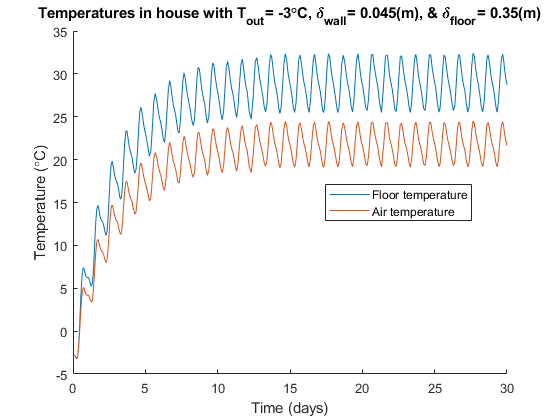


clf
hold on
plot(t/3600/24,T_floor)
plot(t/3600/24, T_air)
xlabel('Time (days)')
ylabel('Temperature (\circC)')
title("Temperatures in house with T_{out}= "+T_out+"\circC, \delta_{wall}= "+delta_wall+"(m), & \delta_{floor}= "+delta_floor+"(m)")
legend('Floor temperature','Air temperature','Location',"best")
hold off

The temperature of the air in the house initially starts really cold, but warms up to reach a comfortable equilibrium temperature around 20 degrees Celcius after about two weeks. This looks like a successful solar house model, where the temperature remains in a comfortable range yet still fluctates throughout the day as we expected it to.

Next steps would include adding more complexity to the model, such as checking how the temperature in the house changes with the seasons, to see if it would still be comfortable and liveable under those conditions or we would need to make modifications.